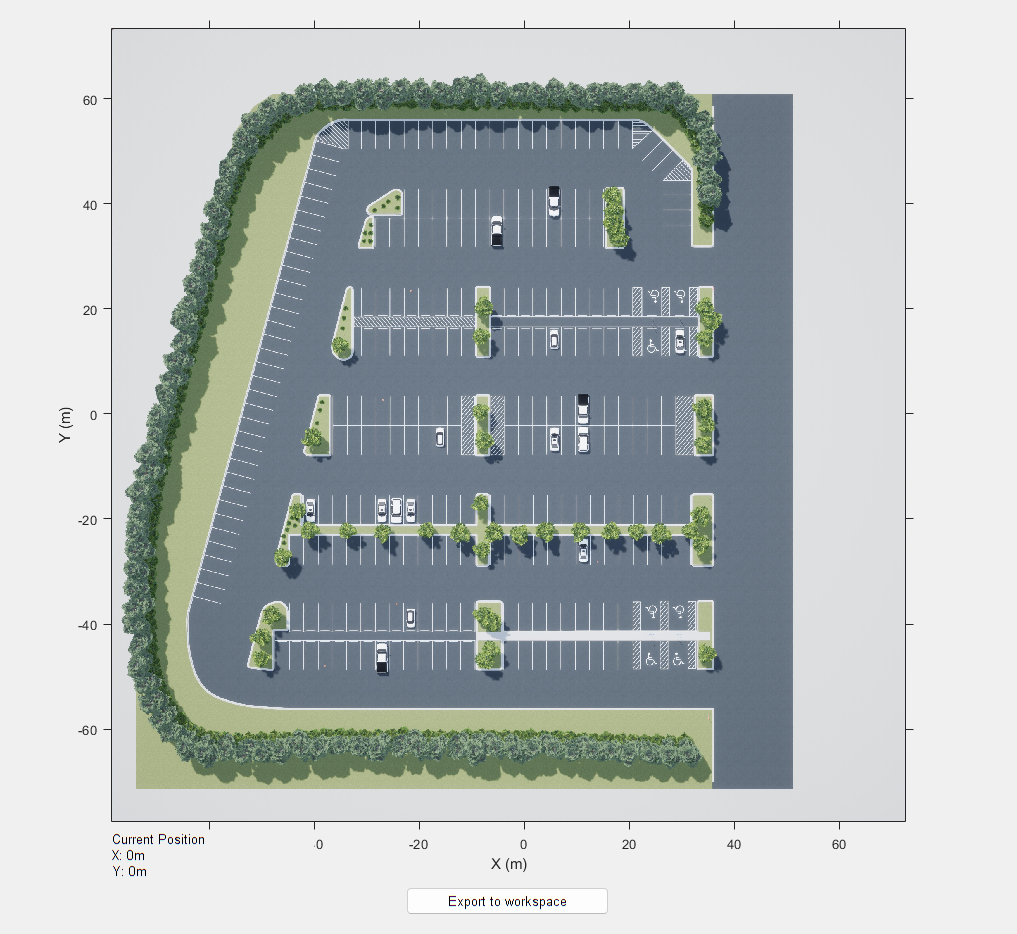

%% 1. Seleziona Waypoints e Generazione Percorso
sceneName = 'LargeParkingLot';
[sceneImage, sceneRef] = helperGetSceneImage(sceneName);

% Seleziona manualmente i waypoints
hFig = helperSelectSceneWaypoints(sceneImage, sceneRef);

% Genera percorso continuo per simulazione 3D
numPoses = size(refPoses{1}, 1);
refDirections  = ones(numPoses,1);   % Movimento in avanti
numSmoothPoses = 20 * numPoses;      % Aumenta la densità delle pose

[smoothRefPoses,~,cumLengths] = smoothPathSpline(refPoses{1}, refDirections, numSmoothPoses);

% Salvare delle pose
refPosesX = smoothRefPoses(:,1);
refPosesY = smoothRefPoses(:,2);
refPosesT = smoothRefPoses(:,3);

save('refPosesX.mat', 'refPosesX');
save('refPosesY.mat', 'refPosesY');
save('refPosesT.mat', 'refPosesT');

%% 2. Configura della simulazione
modelName = 'CustomLidarSLAM';
open_system(modelName);

% Parametri
simStopTime = 10;
set_param(modelName, 'StopTime', num2str(simStopTime));

timeVector = normalize(cumLengths, 'range', [0, simStopTime]);

% Variabili per Simulink
refPosesX = [timeVector, smoothRefPoses(:,1)];
refPosesY = [timeVector, smoothRefPoses(:,2)];
refPosesT = [timeVector, smoothRefPoses(:,3)];

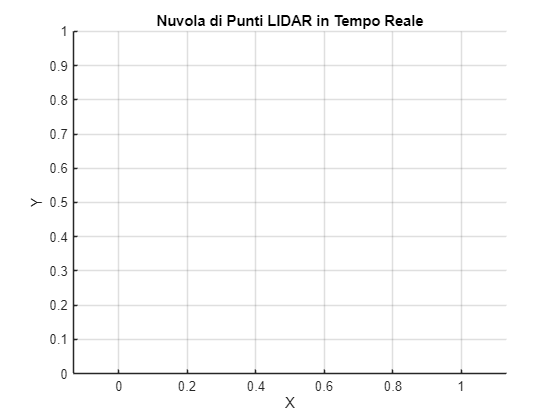

% Estrai i dati LIDAR dalla variabile out
lidarData = out.lidarScans.signals.values;  
numScans = size(lidarData, 4); % Numero totale di scansioni nel tempo

% Creazione della finestra di visualizzazione
figure;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Nuvola di Punti LIDAR in Tempo Reale');
axis equal;
grid on;
colormap jet; % Imposta la mappa di colori per la distanza

% Estrai e visualizza la prima scansione
lidarValues = squeeze(lidarData(:, :, :, 1)); % (32x360x3) -> (N x 3)

Index in position 4 exceeds array bounds.

points3D = reshape(lidarValues, [], 3); % Trasforma in (32*360, 3)

% Calcola la distanza dall'origine per ogni punto
distances = sqrt(sum(points3D.^2, 2)); 

% Creazione dell'oggetto scatter per aggiornamenti in tempo reale
scatterHandle = scatter3(points3D(:, 1), points3D(:, 2), points3D(:, 3), 5, distances, 'filled');
colorbar; % Aggiunge una legenda per il colore basato sulla distanza

% Loop per aggiornare la visualizzazione senza errori
for scanIndex = 2:numScans  
    lidarValues = squeeze(lidarData(:, :, :, scanIndex)); % (32x360x3)  
    points3D = reshape(lidarValues, [], 3); % (32*360, 3)

    % Calcola la distanza dall'origine
    distances = sqrt(sum(points3D.^2, 2)); 

    % Aggiorna la nuvola di punti con colore basato sulla distanza
    set(scatterHandle, 'XData', points3D(:, 1), ...
                       'YData', points3D(:, 2), ...
                       'ZData', points3D(:, 3), ...
                       'CData', distances); % Colore basato sulla distanza
    drawnow;
end